clear all
close all
clc

load('Benchmark_EEG_medium')
load('Benchmark_EEG_small')

PAR = size(EEGdata,1);          % #participants 
REA = size(EEGdata{2}.angle,1); % #realizations

rng(1);

Preprocessing Data

ds = 8

ds = 8


for i = 1:PAR
    for j = 1:REA
out = squeeze(EEGdata{i}.comp(j,:,:))';
in  = squeeze(EEGdata{i}.angle(j,:,:))';

outlierz = isoutlier(mean(out)) | isoutlier(var(out));

out=smoothdata(out(:,~outlierz),'gaussian',4*ds);
in=smoothdata(in(:,~outlierz),'gaussian',4*ds);

outbounds = (max(abs(out))<4);

EEGclean{i}.out{j}=out(1:ds:end,outbounds)/8+0.5;
EEGclean{i}.in{j}=in(1:ds:end,outbounds)/0.12+0.5;
    end
end



% average over periods and downsample, see Section II-B of paper
for Sidx=1:PAR
    smalldata.u(Sidx,:,:)=squeeze(mean(EEGdata{Sidx}.angle(:,:,1:ds:end),2)/0.12+0.5);
    smalldata.y(Sidx,:,:)=squeeze(mean(EEGdata{Sidx}.comp(:,:,1:ds:end),2))/8+0.5;
end

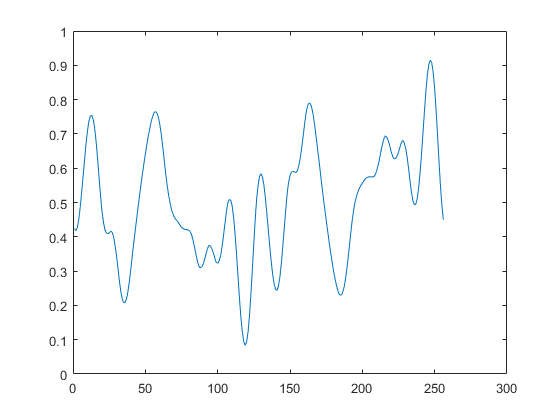


plot(squeeze(smalldata.u(1,1,:)))

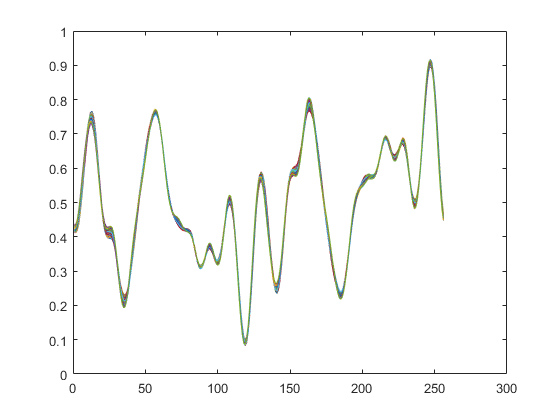

plot(EEGclean{1}.in{1})

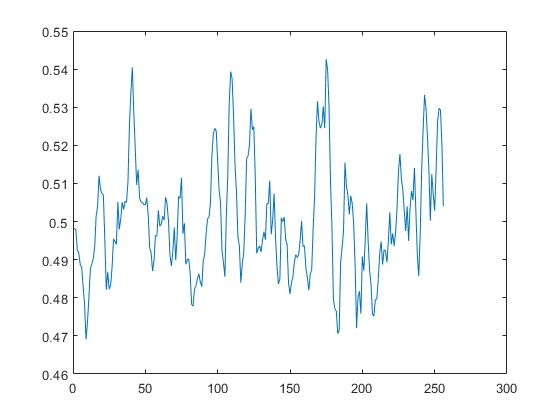


plot(squeeze(smalldata.y(1,1,:)))

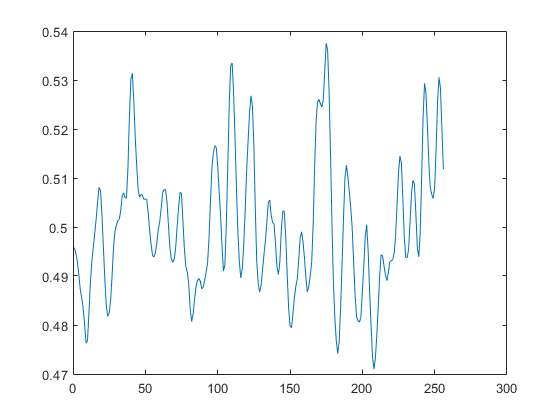

plot(mean(EEGclean{1}.out{1}(:,:)'))


var(squeeze(smalldata.y(1,1,:)))

ans = 2.2485e-04

var(mean(EEGclean{1}.out{1}(:,:)'))

ans = 1.9008e-04

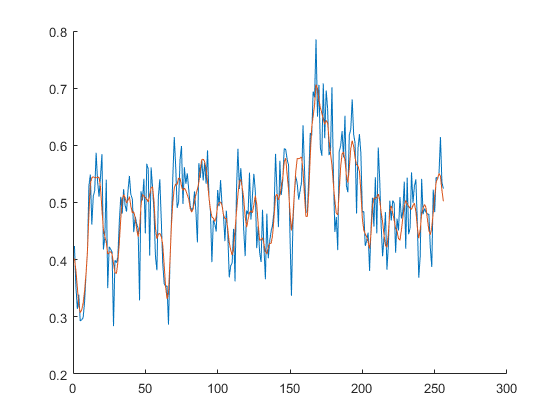


figure;
hold on
plot(squeeze((EEGdata{1}.comp(1,1,1:ds:end))/8+0.5))
plot((EEGclean{1}.out{1}(:,1)))
hold off


FY = mag2db(abs(fft((squeeze((EEGdata{1}.comp(1,1,1:1:end))))/8+0.5)));
FYY = mag2db(abs(fft((squeeze((EEGdata{1}.comp(1,1,1:ds:end))))/8+0.5)));
FZ = mag2db(abs(fft(((EEGclean{1}.out{1}(:,1))))));
FX = mag2db(abs(fft((squeeze(smalldata.y(1,1,:))))))

FX =    42.1465
  -13.7999
   -8.1543
  -35.6674
    2.9308
  -14.9364
  -10.1326
   -5.9869
   -8.4546
  -13.4704


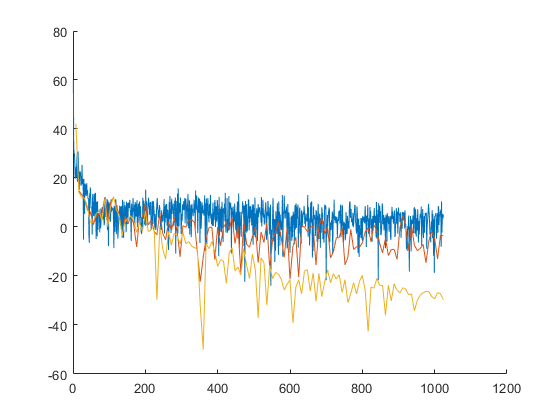


figure;
hold on
plot(FY(1:floor(end/2)))
plot(8:ds:1024,FYY(1:floor(end/2)))
plot(8:ds:1024,FZ(1:floor(end/2)))
% plot(8:ds:1024,FX(1:floor(end/2)))
hold off

partici = 1 

partici = 1


input = [];
output = [];
    for j = 1:REA
input = [EEGclean{partici}.in{j} input];
output = [EEGclean{partici}.out{j} output];
    end
    
tinput = squeeze(smalldata.u(partici,:,:))';
toutput = squeeze(smalldata.y(partici,:,:))';

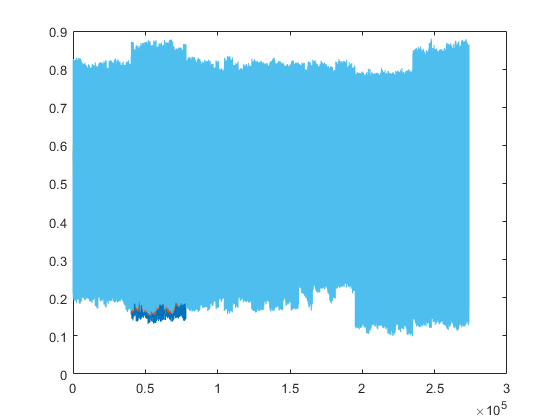

inlags=[6 5 4];
for l = 1:length(inlags)
u(:,l) = (reshape(input(end-inlags(l)-201:end-inlags(l)-1,:), [],1));
end

vlags=[10 9 8 6 5 4];
for l = 1:length(vlags)
v(:,l) = (reshape(input(end-vlags(l)-201:end-vlags(l)-1,:), [],1) - reshape(input(end-vlags(l)-200:end-vlags(l),:), [],1))/0.2+0.5;
end

plot(v)

outlags=[0 1 2 3 4 5];
for l = 1:length(outlags)
y(:,l) = reshape(output(end-outlags(l)-200:end-outlags(l),:), [],1);
end
% -----------------------

for l = 1:length(inlags)
tu(:,l) = reshape(tinput(end-inlags(l)-200:end-inlags(l),:), [],1);
end

for l = 1:length(vlags)
tv(:,l) = (reshape(tinput(end-vlags(l)-201:end-vlags(l)-1,:), [],1) - reshape(tinput(end-vlags(l)-200:end-vlags(l),:), [],1))/0.2+0.5;
end

for l = 1:length(outlags)
ty(:,l) = reshape(toutput(end-outlags(l)-200:end-outlags(l),:), [],1);
end

% autocorr(u(:,l),80)
% autocorr(y(:,l),80)
% 
% parcorr(u(:,l),20)
% parcorr(y(:,l),20)

% heatmap(corr([u y]));


% trainind = randperm(size(u,1),250000);
% testind = setdiff([1:size(u,1)],trainind);

testind = [20000:20200 60000:60200 10000:10200 130000:130200 170000:170200 200000:200200 240000:240200];
trainind = setdiff([1:size(u,1)],testind);

featurez = [u(trainind,:) v(trainind,:) y(trainind,2:end)];
zeta = y(trainind,1);

tfeaturez = [u(testind,:) v(testind,:) y(testind,2:end)];
yt = y(testind,1);

% tfeaturez = [tu tv ty(:,2:end)];
% yt = ty(:,1);

% tfeaturez = featurez(1:400,:);
% yt = zeta(1:400,:);

Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                 %degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;

un = basisvectors(featurez,n,m)

un = 1×14 cell array
    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}    {272355×6 double}


Initialize tensor train

% Choose TT-ranks
maxrank = 5;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank))

r =      1     6    10    10    10    10    10    10    10    10    10    10    10     6     1



for i=1:d
    I(i)=size(un{i},2);
end

% Randomly initialize TT-cores 
init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),I(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.I = I(i);
        init{i}.r(2)=r(i+1);
    end

for i=1:d
    TN.core{i}=init{i}.core;
    TN.sz(i,:)=[init{i}.r(1),init{i}.I,init{i}.r(2)];
end

Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},un{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*I(i),r(i)]); 
end


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression =' dof/Pcount])  %ratio

Compression = 


Choose regularization matrix


difforder=2;
P = diff(eye(In),difforder);
PP = P'*P;

Choose optimization options

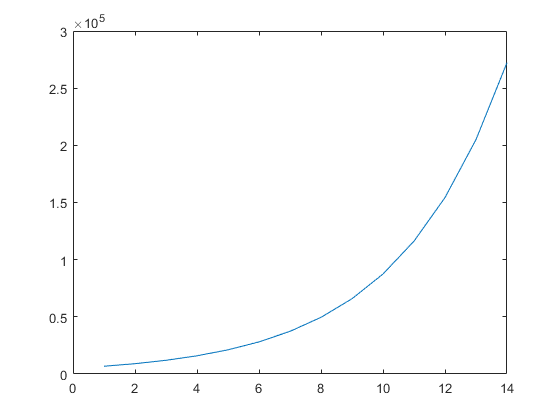


res1=[];
res2=[];
MAXITR = d;
bb=1;
itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated


nselect = floor(logspace(log10(dof/N),0,MAXITR)*N);

plot(nselect);

% itr=1;  
% MAXITR =  d;
% nselect=N*ones(MAXITR,1);



gamma=0.00000001

gamma = 1.0000e-08

% lambda = 0.01;
% gamma=1*10^-2;
 tic

% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while (itr < MAXITR )
%     ---------------------updateTT-----------------;
        
dataselect = randperm((N),nselect(itr));
% dataselect = 1:N;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),un{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
%         -------------------difference penalty 

        for j=1:d
        Csize = TN.sz(j,:);
        
        Dm = reshape(permute(TN.core{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
        mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        PD = P*Dm;
        DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
        eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
        end
        eyez{d+1}=1;
        
        for p= 1:d
            Dsize = TN.sz(sweepindex,:);   
                if sweepindex==p
                    D1 = eyez{sweepindex};
                    D2 = PP(:);
                    D3 = eyez{sweepindex+1};
                elseif sweepindex<p
                    D1 = eyez{sweepindex};  
                    D2 = eyep{sweepindex};   
                    D3= DWD{p}*eyez{p+1};           
                    for it=(p-1):-1:(sweepindex+1)               
                        D3 = DD{it}*D3;
                    end                               
                elseif sweepindex>p   
                    D1= eyez{p}'*DWD{p};
                    for it=(p+1):(sweepindex-1)               
                        D1 = D1*DD{it};
                    end
                    D1=D1';
                    D2 = eyep{sweepindex};   
                    D3= eyez{sweepindex+1}; 
                end
          
            WW = kron(D3, kron(D2, D1));
            Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
            W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]); 
        end
        WWW = W{1};
        for s =2:d
            WWW = WWW + W{s};
        end
        
        Wopslag{itr} = W;
%         ----------------------- 
%         D = eye(r(sweepindex)*(I(sweepindex))*r(sweepindex+1));         
        AA = A'*A;
        bb = bb+1;
        
      lambda = 1; %sqrt(trace(AA)/trace(WWW));

       
        Tracez(bb) = trace(AA);
         Wcez(bb) = trace(WWW);
         
%          tic
        g=pinv(AA + gamma*lambda*WWW)*(A'*zeta(dataselect,:));
%         mister(bb) = toc;
%         tic
%         [g,~] = pcg((AA + lambda*WWW),(A'*zeta(dataselect,:)),10^-6,100,[],[],TN.core{sweepindex}(:));
        
%         sister(bb) = toc;
        
        
        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
%             TN.core{sweepindex}=reshape(g,[r(sweepindex),I(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(I(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),I(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(I(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),I(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},un{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*I(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
%             TN.core{sweepindex}=reshape(g,[r(sweepindex),I(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(I(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),I(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(I(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),I(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},un{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*I(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-zeta(dataselect,:))^2/(nselect(itr)); % check residual
            res2(itr)=1*(g'*g);
            res3(itr)=1*(g'*WWW*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end
            end
            
            itr=itr+1; %update iteration
            
            disp(["iteration:" itr timer])
        end   
end  

    "iteration:"    "2"    "2.4264"

    "iteration:"    "3"    "5.0117"

    "iteration:"    "4"    "7.8564"

    "iteration:"    "5"    "10.9185"

    "iteration:"    "6"    "14.2595"

    "iteration:"    "7"    "18.049"

    "iteration:"    "8"    "22.4315"

    "iteration:"    "9"    "27.5014"

    "iteration:"    "10"    "33.6951"

    "iteration:"    "11"    "41.372"

    "iteration:"    "12"    "50.9937"

    "iteration:"    "13"    "62.7968"

    "iteration:"    "14"    "77.8705"



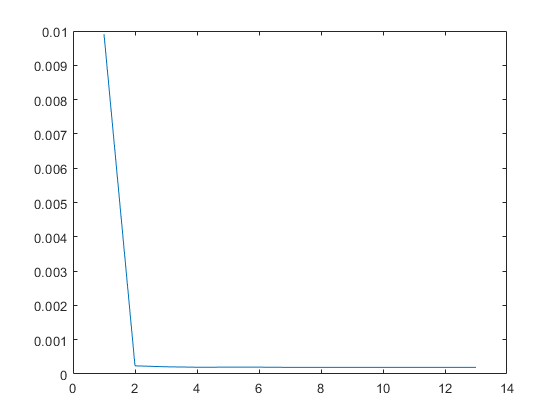

plot(res1)

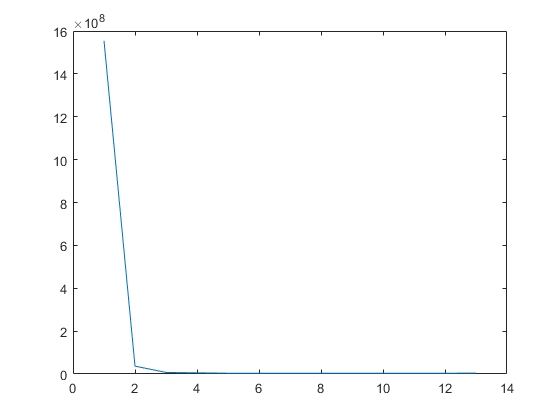

plot(res2)

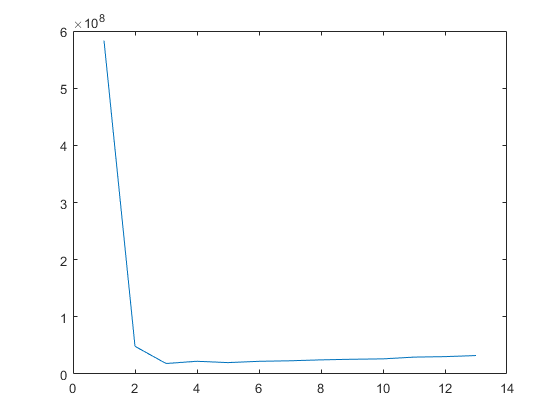

plot(res3)

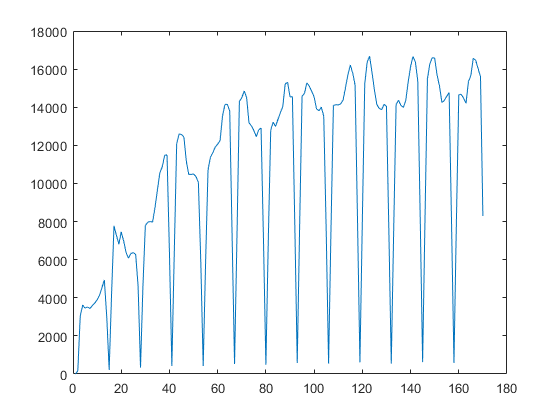


plot(Wcez)

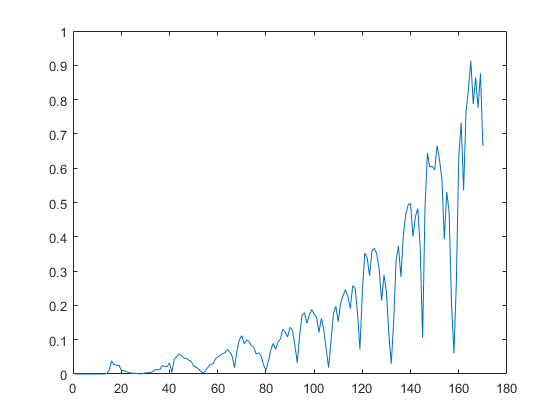

plot(Tracez)

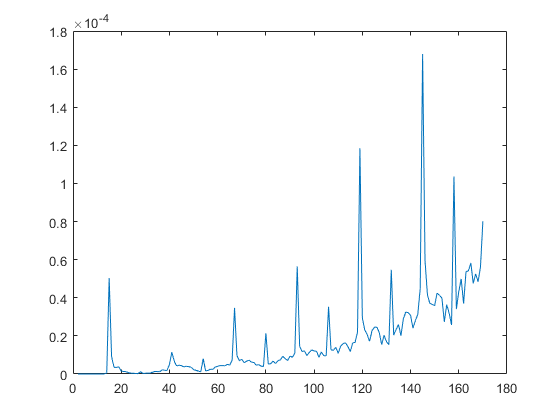

plot(Tracez./Wcez)

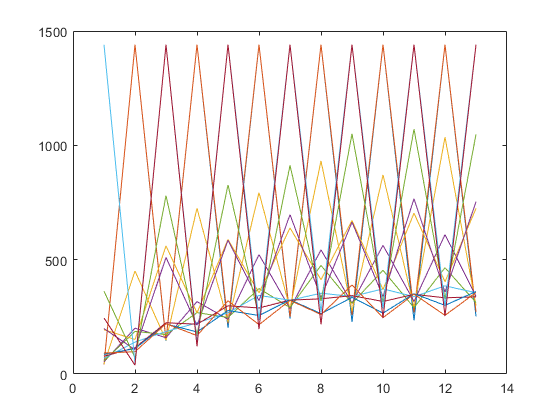


for k = 1:d
    for cud = 1:MAXITR-1
plottester(k,cud) = trace(Wopslag{cud}{k});
end
end
plot(plottester')


% axis([-inf inf 0 100])

figure;
hold on
tic
 plot(pinv(AA + lambda*WWW)*(A'*zeta(dataselect,:)));
   toc; tic 

Elapsed time is 0.056608 seconds.


 plot(pcg(   (AA + lambda*WWW),(A'*zeta(dataselect,:)),10^-6,1000));

pcg converged at iteration 20 to a solution with relative residual 5.6e-07.


toc; tic 

Elapsed time is 0.108413 seconds.


 plot(cgs(   (AA + lambda*WWW),(A'*zeta(dataselect,:)),10^-6,1000));

cgs converged at iteration 12 to a solution with relative residual 2.4e-07.


toc

Elapsed time is 0.048262 seconds.


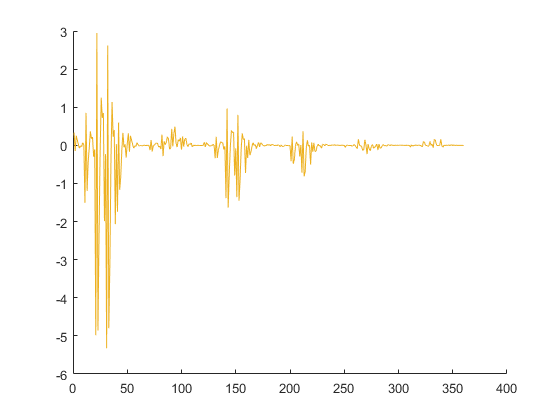

hold off

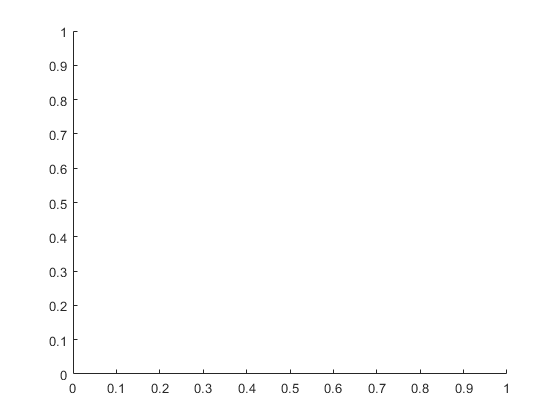


figure;
hold on
% plot(mister)
% plot(sister)
hold off

Evaluate Test data


[Nt, dt]=size(tfeaturez);

In= m+n;

bs = bspline([0:n+1]);
M = flipud(bs.coefs)';

knotdist = 1/m;

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>m)= m;

inputs = (tfeaturez/knotdist)-indexes+1;

for i=1:dt
bn = inputs(:,i).^[n:-1:0]*M;

ut{i} = zeros(Nt,In);
for ii=1:Nt
   ut{i}(ii,indexes(ii,i):indexes(ii,i)+n) = bn(ii,:);
end
end

yhat=zeros(Nt,1);

G = TN.core;

for i = 1:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end


for jj=1:Nt   
f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i}(:,:,jj);
end
yhat(jj)=f;
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(Nt,1);
Vp{d}=ones(Nt,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},ut{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*I(i),r(i)]); 
end

yhat = ones(Nt,1);
for i=1:d
    yhat=dotkron(yhat,ut{i})*reshape(TN.core{i},[r(i)*I(i),r(i+1)]); 
end
norm(Vm{end}- yhat)

Error using  - 
Matrix dimensions must agree.

i=1
% dotkron(Vm{1},ut{1}*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*I(i),r(i)]),Vp{1})
norm(dotkron(Vp{i},ut{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*I(i),r(i)]) - yhat)
% ut{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*I(i),r(i)])

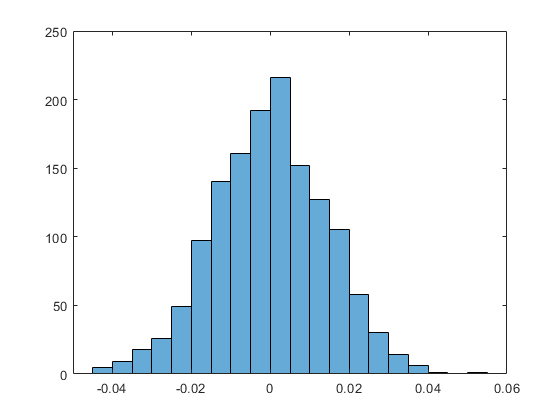



erboi = (yhat-yt);
histogram((erboi)')

VAF = 1-var(erboi)/var(yt)

VAF = 0.9779

MSE = immse(yhat,yt)

MSE = 2.0467e-04

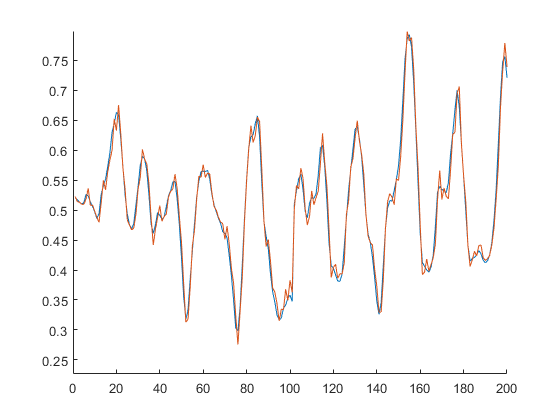


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 200 -inf inf])

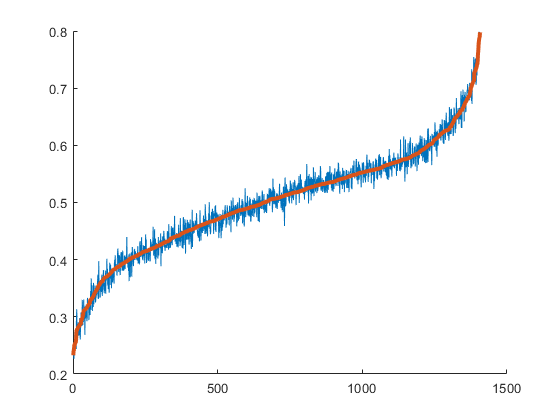


[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

meanVAF = mean(VAF)

meanVAF = 0.9779



% plot(erboi)
pererror = sum(abs(erboi))/Nt

pererror = 0.0113

relerror = sum(abs(erboi)/sum(abs(yt)))

relerror = 0.0226

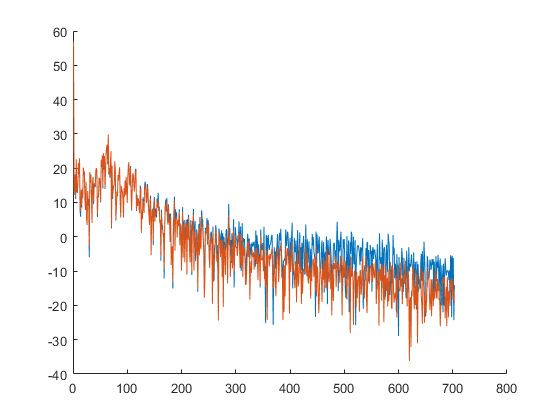


FY = mag2db(abs(fft(yhat)));
FZ = mag2db(abs(fft(yt)));

figure;
hold on
plot(FY(1:floor(end/2)))
plot(FZ(1:floor(end/2)))
hold off


% ploterrcorr(erboi')
% autocorr(erboi')




% smoothed= smoothdata(output,'sgolay',20); 
% figure;
% hold on
% plot(output)
% plot(refer)
% % plot(smoothed)
% hold off

Mdl = arima(4,4,4)

Mdl =   arima with properties:

     Description: "ARIMA(4,4,4) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 8
               D: 4
               Q: 4
        Constant: NaN
              AR: {NaN NaN NaN NaN} at lags [1 2 3 4]
             SAR: {}
              MA: {NaN NaN NaN NaN} at lags [1 2 3 4]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

EstMdl = estimate(Mdl,zeta)

 
    ARIMA(4,4,4) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    6.5957e-08     4.6261e-07       0.14258         0.88663
    AR{1}         -0.95568       0.012174       -78.505               0
    AR{2}           -1.066      0.0081809       -130.31               0
    AR{3}         -0.18662      0.0030065       -62.072               0
    AR{4}         -0.22918      0.0022001       -104.17               0
    MA{1}         -0.94343        0.01216       -77.586               0
    MA{2}         -0.16752       0.022868       -7.3255      2.3809e-13
    MA{3}         -0.77097 

EstMdl =   arima with properties:

     Description: "ARIMA(4,4,4) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 8
               D: 4
               Q: 4
        Constant: 6.59573e-08
              AR: {-0.95568 -1.06603 -0.18662 -0.229183} at lags [1 2 3 4]
             SAR: {}
              MA: {-0.943427 -0.167521 -0.770975 0.892416} at lags [1 2 3 4]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.000525768

for i = 1:90
testers(:,i) = forecast(EstMdl,1,yt(i:i+7));
end


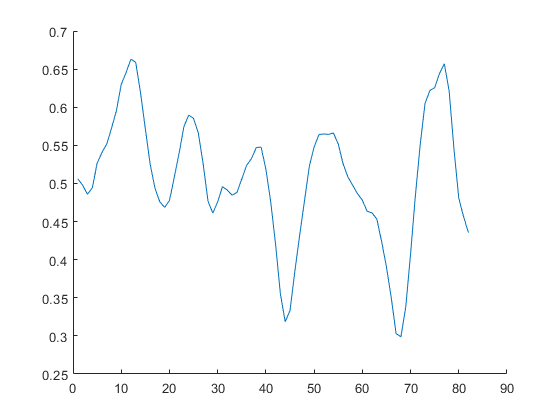


figure
hold on
plot(yt(9:90))

plot(testers(3,:))

Index in position 1 exceeds array bounds (must not exceed 1).

hold off
